# The Gauntlet Challenge

#### *By Vaani Bhatnagar and Tara Lee*

## Gauntlet Map

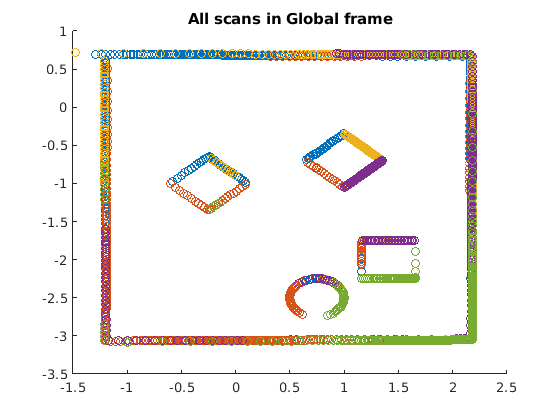

scans()
map()

## Contour Map

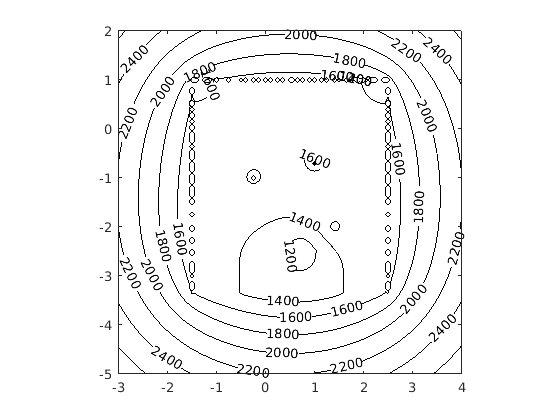

% sink is (+), goes from high to low, trough
% source is (-), goes from low to high, peak
% potential field arrows go from low to high

[x,y]=meshgrid(-3:0.05:4,-5:0.05:2);

% right wall
w1 = 0;
for a = -1.5:0.01:2.5
    w1 = w1 - log(sqrt((x-a).^2 + (y-1).^2));
end

% left wall
w2 = 0;
for a = -1.5:0.01:2.5
    w2 = w2 - log(sqrt((x-a).^2 + (y+3.37).^2));
end

% top wall
w3 = 0;
for a = -3.37:0.01:1
    w3 = w3 - log(sqrt((x+1.5).^2 + (y-a).^2));
end

% bottom wall
w4 = 0;
for a = -3.37:0.01:1
    w4 = w4 - log(sqrt((x-2.5).^2 + (y-a).^2));
end

% barrel of benevolence
bob = 0;
for theta = 0:0.1:2*pi
a = 0.75+0.25.*cos(theta);
b = -2.5+0.25.*sin(theta);
bob = bob + log(sqrt((x-a).^2 + (y-b).^2));
end

% obstacle 1
o1 = log(sqrt((x+0.25).^2+(y+1).^2));

% obstacle 2
o2 = log(sqrt((x-1).^2+(y+0.7).^2));

% obstacle 3
o3 = log(sqrt((x-1.41).^2+(y+2).^2));

v = 3*bob - 50*o1 - 40*o2 - 90*o3 - w1 - w2 - w3 - w4;
% w = 3*log(sqrt((x-0.75).^2+(y+2.5).^2));
% v = 20*w - 20*log(sqrt((x+0.25).^2+(y+1).^2)) - 20*log(sqrt((x-1).^2+(y+0.7).^2)) - 50*log(sqrt((x-1.41).^2+(y+2).^2)) - w1 - w2 - w3 - w4;
figure;
contour(x,y,v,'k','ShowText','On')
axis equal

save('equation.mat','bob','o1', "o2", 'o3', 'w1', 'w2', 'w3', "w4", 'v');

## Quiver and Contour Map

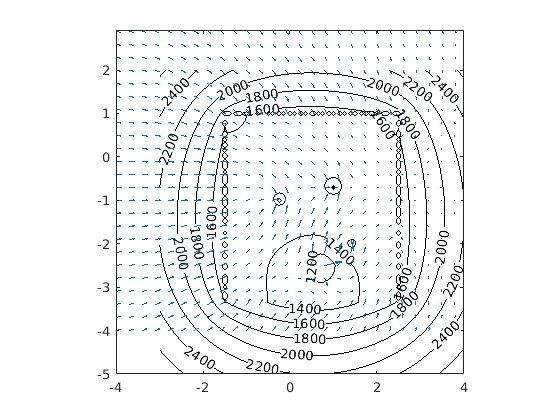

hold on
[x,y]=meshgrid(-4:0.3:4,-4:0.3:3);

% right wall
w1_x = 0;
w1_y = 0;
for a = -1.5:0.01:2.5
    w1_x = w1_x + ((x-a)./((x-a).^2 + (y).^2)-1);
    w1_y = w1_y + ((y-1)./((x-a).^2 + (y-1).^2));
end

% left wall
w2_x = 0;
w2_y = 0;
for a = -1.5:0.01:2.5
    w2_x = w2_x + ((x-a)./((x-a).^2 + (y+3.37).^2));
    w2_y = w2_y + ((y+3.37)./((x-a).^2 + (y+3.37).^2));
end

% top wall
w3_x = 0;
w3_y = 0;
for a = -3.37:0.01:1
    w3_x = w3_x + ((x+1.5)./((x+1.5).^2+(y-a).^2));
    w3_y = w3_y + ((y-a)./((x+1.5).^2+(y-a).^2));
end

% bottom wall
w4_x = 0;
w4_y = 0;
for a = -3.37:0.01:1
    w4_x = w4_x + ((x-2.5)./((x-2.5).^2+(y-a).^2));
    w4_y = w4_y + ((y-a)./((x-2.5).^2+(y-a).^2));
end

fx = 100*((x-0.75)./((x-0.75).^2+(y+2.5).^2)) - 75*((x+0.25)./((x+0.25).^2+(y+1).^2)) - 75*((x-1)./((x-1).^2+(y+0.7).^2)) - 50*((x-1.41)./((x-1.41).^2+(y+2).^2)) - w1_x - w2_x - w3_x - w4_x;
fy = 500*((y+2.5)./((x-0.75).^2+(y+2.5).^2)) - 375*((y+1)./((x+0.25).^2+(y+1).^2)) - 375*((y+0.7)./((x-1).^2+(y+0.7).^2)) - 250*((y+2)./((x-1.41).^2+(y+2).^2)) - w1_y - w2_y - w3_y - w4_y;

% fx = ((x-0.75)./((x-0.75).^2+(y+2.5).^2)) - ((x+0.25)./((x+0.25).^2+(y+1).^2)) - ((x-1)./((x-1).^2+(y+0.7).^2)) - ((x-1.41)./((x-1.41).^2+(y+2).^2)) - w1_x - w2_x - w3_x - w4_x;
% fy = ((y+2.5)./((x-0.75).^2+(y+2.5).^2)) - ((y+1)./((x+0.25).^2+(y+1).^2)) - ((y+0.7)./((x-1).^2+(y+0.7).^2)) - ((y+2)./((x-1.41).^2+(y+2).^2)) - w1_y - w2_y - w3_y - w4_y;

quiver(x,y,fx,fy)
axis equal

## Encoder Data and Path

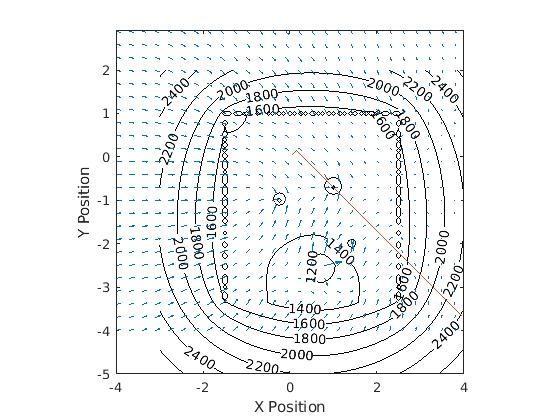

hold on
data=csvread('encoderData.csv',20,0);   % read the csv file, skip header row
plot(data(:,2),-data(:,3))            % plot 2nd column vs 1st
xlabel('X Position')
ylabel('Y Position')

## Running The Neato

% flatland()